**Problem 1.**

*Solve the following circuit for i1, i2, and i3 using the mesh current technique and linsolve().*

    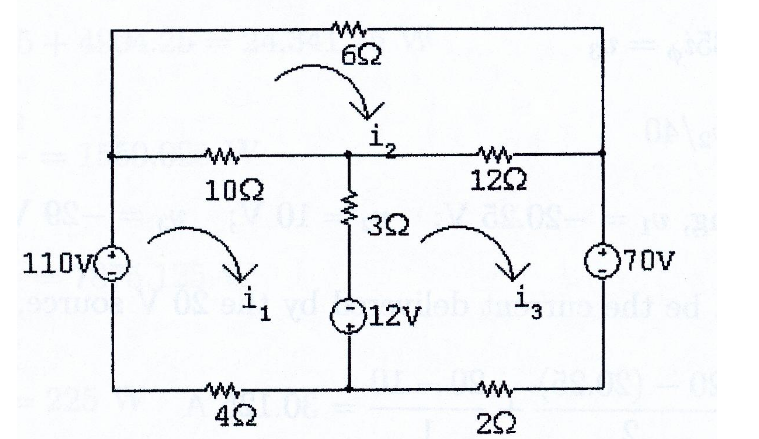

To begin this problem we pick out the three mesh-current equations and set them equal to zero.

$i_1$:


$$-110+10(i_1-i_2)+3(i_1-i_3)-12+4i_1=0$$



$$i_2:$$



$$10(i_2-i_1)+6i_2+12(i_2-i_3)=0$$



$$i_3:\\
12+3(i_3-i_1)+12(i_3-i_2)+70+2i_3=0$$


simplifying these equations we get:


$$17i_1-10i_2-3i_3=122\\
-10i_1+28i_2-12i_3=0\\
-3i_1-12i_2+13i_3=-82$$


which lead to the following matrix equation:


$$\left\lbrack \begin{array}{ccc}
17 & -10 & -3\\
-10 & 28 & -12\\
-3 & -12 & 17
\end{array}\right\rbrack \times \left\lbrack \begin{array}{c}
i_1 \\
i_2 \\
i_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
122\\
0\\
-82
\end{array}\right\rbrack$$


Now we can use Matlab to solve the equation...

A=[17,-10,-3;-10,28,-12;-3,-12,17]

A =     17   -10    -3
   -10    28   -12
    -3   -12    17


B=[122,0,-82]'

B =    122
     0
   -82


linsolve(A,B)

ans =      8
     2
    -2


This result tells us that the mesh currents for $i_1,\ i_2,$ and $i_3$ are 8, 2, and -2 amps, respectively.

**Problem 2.**

*Plot the trajectory of a cannonball fired from 1 meter above ground at 120 meters/second at angles 0, 20, 45, 60 degrees (up) all on one plot (four plots). Label the plot and axes and show a legend so we can tell which plot goes with which angle. Note: Matlab assumes angles are in radians. Assume the cannonball stops when it hits the ground.*

I watched this youtube video for a projectile motion refresher:

    [https://www.youtube.com/watch?v=M8xCj2VPHas](https://www.youtube.com/watch?v=M8xCj2VPHas)

When the cannonball is fired at an angle of 0 degrees, we have the following information:

v0=120 % m/s initial velocity

v0 = 120

y0=1 %m initial y coordinate

y0 = 1

x0=0 %m initial x coordinate

x0 = 0

G=-9.8 %m/s^2 force of gravity or acceleration in the 

G = -9.8000

To solve this trajectory problem we will use the displacement equation:


$$S=\frac12at^2+v_0t+S_0$$


which we can then break down into equations for the x and y axes:


$$x=\frac12a_xt^2+v_{0x}t+x_0\\
=v_0  cos\theta  t\\
y=\frac12a_yt^2+v_{0y}t+y_0\\
=\frac12Gt^2+v_0sin \theta t + y_0$$


We then plug these equations into matlab and plot the results

t=0:.1:100;

for $\theta = 0^{\circ}$

x1=v0*cos(0)*t;
y1=(1/2)*G*t.^2+v0*sin(0)*t+y0;
plot(x1,y1)

hold on

for $\theta=20^{\circ}$

x2=v0*cos(20*(pi/180))*t;
y2=(1/2)*G*t.^2+v0*sin(20*(pi/180))*t+y0;
plot(x2,y2)

for $\theta = 45^{\circ}$

x3=v0*cos(45*(pi/180))*t;
y3=(1/2)*G*t.^2+v0*sin(45*(pi/180))*t+y0;
plot(x3,y3)

for $\theta=60^{\circ}$

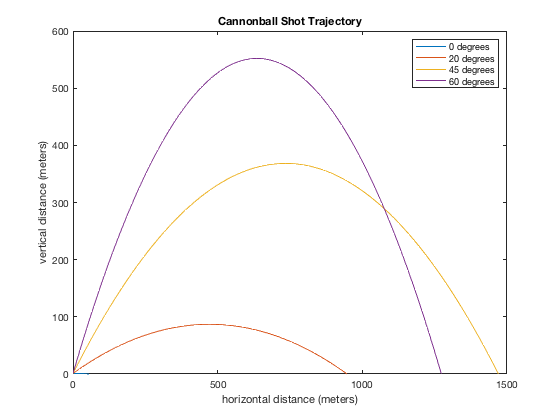

x4=v0*cos(60*(pi/180))*t;
y4=(1/2)*G*t.^2+v0*sin(60*(pi/180))*t+y0;
plot(x4,y4)
legend('0 degrees','20 degrees','45 degrees','60 degrees');

title('Cannonball Shot Trajectory')
xlabel('horizontal distance (meters)')
ylabel('vertical distance (meters)')

hold off
ylim([0 600])

As we see from the graph when the cannonball is shot at an angle of 0 degrees, it dives to zero very quickly. We also see that, just as we'd expect, the cannonball shot at an angle of 45 degrees flies the furthest.

**Problem 3.**

*This problem came up in someone's senior project. Consider the following voltage divider*

    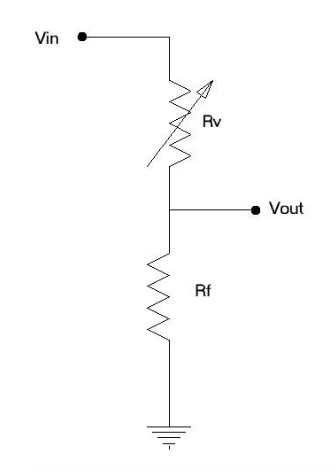

*If *$R_v$ varies between some $R_{min}$ and $R_{max}$ ($0<R_{min}\leq R_v \leq R_{max}$), what value of $R_f$ gives the greatest (largest) range of $V_{out}$? In other words as $R_v$ varies between $R_{min}$ and $R_{max}$ then $v_{out}$ varies between some $V_{min}$ and $V_{max}$:

                
$$V_{min} \leq V_{out} \leq V_{max}$$


Without loss of generality, assume that $V_{in}=$1 volt, then$V_{min}=\frac{(R_f)}{R_f+R_{max}}$ and $V_{max}=\frac{(R_f)}{R_f+R_{min}}$ and $\Delta V=V_{max}-V{min}$. We want to find the value of $R_f$ that maximizes$\Delta V$.

Solve this problem using the symbolic toolbox. Generally follow these steps:

    $\cdot$Define $R_f$, $R_{max}$, and $R_{min}$ as symbolic using *syms*

    $\cdot$Use diff() to find the derivative of $\Delta V$ with respect to $R_f$

    $\cdot$Solve for the value of $R_f$ that makes this derivative go to zero

syms rf rmin rmax
vmin=rf/(rf+rmax)

$$vmin = \frac{\mathrm{rf}}{\mathrm{rf}+\mathrm{rmax}}$$

vmax=rf/(rf+rmin)

$$vmax = \frac{\mathrm{rf}}{\mathrm{rf}+\mathrm{rmin}}$$

dv=vmax-vmin

$$dv = \frac{\mathrm{rf}}{\mathrm{rf}+\mathrm{rmin}}-\frac{\mathrm{rf}}{\mathrm{rf}+\mathrm{rmax}}$$

diff(dv)

$$ans = \frac{\mathrm{rf}}{{\left(\mathrm{rf}+\mathrm{rmax}\right)}^{2}}-\frac{\mathrm{rf}}{{\left(\mathrm{rf}+\mathrm{rmin}\right)}^{2}}-\frac{1}{\mathrm{rf}+\mathrm{rmax}}+\frac{1}{\mathrm{rf}+\mathrm{rmin}}$$

solve(rf/((rf+rmax).^2)-rf/((rf+rmin).^2)-1/(rf+rmax)+1/(rf+rmin)==0,rf)

$$ans = \left(\begin{array}{c} -\sqrt{\mathrm{rmax}\,\mathrm{rmin}}\\ \sqrt{\mathrm{rmax}\,\mathrm{rmin}} \end{array}\right)$$